clc; % clear the command line
addpath(genpath('./.'));  % Add folder and sub-folder to path
dbstop if error  % activate debug in error

## DATA CREATION

This section gather all possible way to create the data. |gen| struct store the parameter and |data_generation.m| compute everything

% Grid size
gen.xmax = 100; %total length in unit [m]
gen.ymax = 100; %total hight in unit [m]

% Scale define the subdivision of the grid (multigrid). At each scale, the
% grid size is $(2^gen.sx+1) \times (2^gen.sy+1)$ 
gen.sx = 10;
gen.sy = 10;

% Generation Method: All method generate with FFTMA a gaussian field.
% 'Normal-Random'              with normal distribution \sim N(gen.mu,gen.std)
% 'LogNormal'   
% 'fromRho':            log transform it with the parameter defined below 
% 'fromK':              generate with FFTMA a field of Hyraulic conductivity and log transform it with the parameter defined below 
gen.method              = 'Normal-Random';

% Generation parameter
gen.samp                = 2;          % Method of sampling of K and g | 1: borehole, 2:random. For fromK or from Rho only
gen.samp_n              = 500;          % number of well or number of point
gen.covar.modele        = [4 20 20 0]; %; 1 1 1 0]; % covariance structure
gen.covar.c             = [1];% 0.01]; 
gen.mu                  = 0; % parameter of the first field. 
gen.std                 = 1;
%gen.Rho.method          = 'R2'; % 'Paolo' (default for gen.method Paolo), 'noise', 'RESINV3D'

% Other parameter
gen.plotit              = false;      % display graphic or not (you can still display later with |script_plot.m|)
gen.saveit              = true;       % save the generated file or not, this will be turn off if mehod Paolo or filename are selected
gen.name                = '100x100-20x20';
gen.seed                = 123456;

% Run the function
data_generation(gen);
%[fieldname, grid_gen, K_true, phi_true, sigma_true, K, sigma, Sigma, gen] = data_generation(gen);


%% SGSIM
% Generation of the high resolution electrical conductivity (sSigma) from
% scarse electrical  data (sigma) and large scale inverted ERt (Sigma).
load('data_gen/data/GEN-100x100-20x20_2016-04-01_16-30');
parm.gen=gen;

parm.n_realisation  = 1;
parm.par = 0;

%parm.name           = 'test_grad_def';
%
% parm.k.nb_neigh = [0 0 0 0 0; 4 4 4 4 4];
%parm.plot.krig =1;
% 
% parm.fitvar         = 0;
% 
% parm.seed           = rand();
% parm.neigh          = true;
% parm.cstk           = false;
parm.nscore         = false;
% parm.unit           = 'Electrical Conductivitiy';
% 
% % Saving

% parm.name           = gen.name;
% 
% % Ploting
% parm.plot.bsgs      = 0;
% parm.plot.ns        = 0;
% parm.plot.sb        = 0;
% parm.plot.kernel    = 0;
% parm.plot.fitvar    = 0;
% parm.plot.krig        = 1;
% 
% parm.k.range.min = [min(sigma.d(:))-2 min(Sigma.d(:))-2];
% parm.k.range.max = [max(sigma.d(:))+2 max(Sigma.d(:))+2];

sigma.d=[];
sigma.x=[];
sigma.y=[];
sigma.n=0;

parm.cstk = false;
parm.saveit = false;
parm.scale = [7;7];

parm.n_realisation  = 50;
[~, t_nocstk_50, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);

## Time Computation

load('data_gen/data/GEN-100x100-20x20_2016-04-01_16-30');
parm.gen=gen;

parm.par = 0;
sigma.d=[];
sigma.x=[];
sigma.y=[];
sigma.n=0;
parm.saveit = false;
parm.nscore         = false;
parm.scale = [7;7];

parm_cstk= [0 1];
parm_n_realisation=[1 5 10]% 50];

parm_n_realisation =      1     5    10



for parm_cstk_i=1:length(parm_cstk)
    for parm_n_realisation_i=1:length(parm_n_realisation)
        parm.cstk = parm_cstk(parm_cstk_i);
        parm.n_realisation  = parm_n_realisation(parm_n_realisation_i);
        [~, t{parm_cstk_i}{parm_n_realisation_i}, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);
    end
end

Error using SGSIM (line 116)
You need to define parm.covar or parm.gen




t_fixe = 1;
t_init = 4;
t_krig = 20;
real_lim=50;
for real_i = 1:real_lim
    Y(real_i,:)=[t_fixe, t_init*real_i, t_krig, t_krig*(real_i-1)];
end
figure; hold on;
area(Y)
plot(1, t_cstk_1.global,'x','linewidth',5,'markersize',10)
plot(1, t_cstk_1.global-t_cstk_1.cstk,'x','linewidth',5,'markersize',10)
plot(1, t_nocstk_1.global,'x','linewidth',5,'markersize',10)

plot(5, t_cstk_5.global,'x','linewidth',5,'markersize',10)
plot(5, t_cstk_5.global-t_cstk_5.cstk,'x','linewidth',5,'markersize',10)
plot(5, t_nocstk_5.global,'x','linewidth',5,'markersize',10)

plot(10, t_cstk_10.global,'x','linewidth',5,'markersize',10)
plot(10, t_cstk_10.global-t_cstk_10.cstk,'x','linewidth',5,'markersize',10)
plot(10, t_nocstk_10.global,'x','linewidth',5,'markersize',10)

plot(50, t_cstk_50.global,'x','linewidth',5,'markersize',10)
plot(50, t_cstk_50.global-t_cstk_50.cstk,'x','linewidth',5,'markersize',10)
plot(50, t_nocstk_50.global,'x','linewidth',5,'markersize',10)

xlabel('Realisation')
ylabel('Time [sec]')
legend('Constant general','General','1 realisation kriging', 'kriging','Measured Data')


##  Unconditional Biais ?

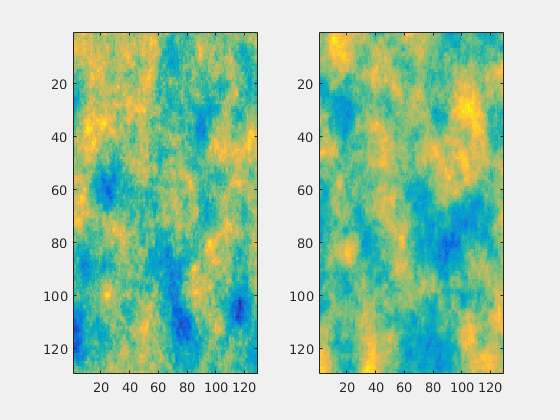

load('data_gen/data/GEN-100x100-20x20_2016-04-01_16-30');
parm.gen=gen;
parm.par = 0;
parm.scale = [7;7];
parm.nscore = false;

sigma.d=[];
sigma.x=[];
sigma.y=[];
sigma.n=0;

parm.n_realisation  = 400;

parm.name = 'cond-400-noMG-noCstk';
parm.cstk = true;

% SGSIM(sigma,sigma_true,grid_gen,parm);


load('result-SGSIM/SIM-uncond-400-noMG-Cstk_2016-04-04_14-18-22')
Res1 = cat(3, Res{1}.m{:});

load('result-SGSIM/SIM-uncond-400-noMG-noCstk_2016-04-04_13-48-08')
Res2 = cat(3, Res{1}.m{:});

figure(1); title('Spatial Average: Cstk (left), noCstk (right)')
subplot(1,2,1); imagesc(mean(Res1,3)); ac=caxis;
subplot(1,2,2); imagesc(mean(Res2,3)); caxis(ac)

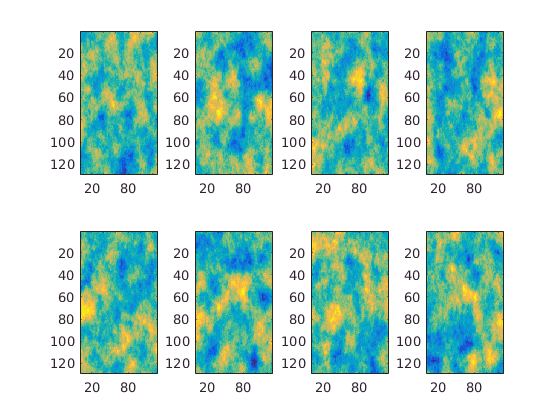


figure(2); title('Spatial Average: Cstk (line 1), noCstk (line 2)')
subplot(2,4,1); imagesc( Res1(:,:,1)); ac=caxis;
subplot(2,4,2); imagesc( Res1(:,:,2)); caxis(ac)
subplot(2,4,3); imagesc( Res1(:,:,3)); caxis(ac)
subplot(2,4,4); imagesc( Res1(:,:,4)); caxis(ac)
subplot(2,4,5); imagesc( Res2(:,:,1)); caxis(ac)
subplot(2,4,6); imagesc( Res2(:,:,2)); caxis(ac)
subplot(2,4,7); imagesc( Res2(:,:,3)); caxis(ac)
subplot(2,4,8); imagesc( Res2(:,:,4)); caxis(ac)

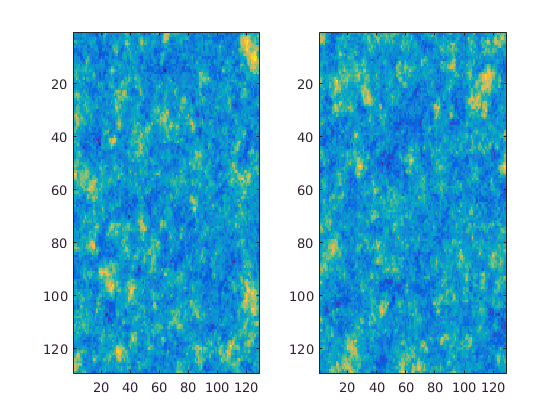


figure(3); title('Spatial Extremum: Cstk (left), noCstk (right)')
subplot(1,2,1); imagesc(max(abs(Res1),[],3)); ac=caxis;
subplot(1,2,2); imagesc(max(abs(Res2),[],3)); caxis(ac)

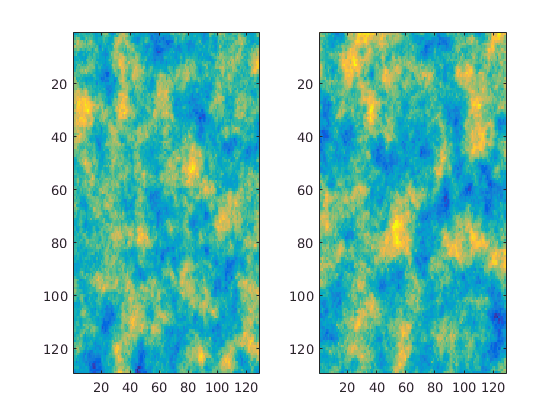


figure(4); title('Spatial Variance: Cstk (left), noCstk (right)')
subplot(1,2,1); imagesc(var(Res1,0,3)); ac=caxis;
subplot(1,2,2); imagesc(var(Res2,0,3)); caxis(ac)

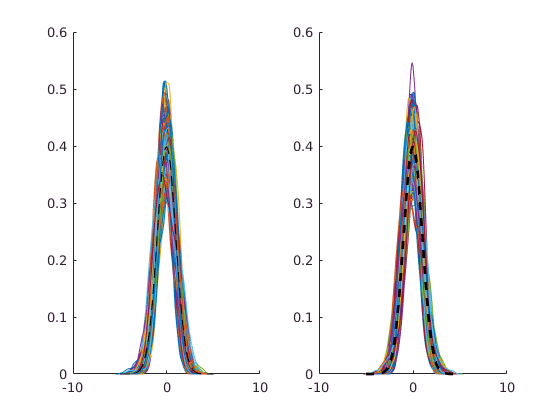


figure(5);clf; title('Histogram')
ksdensity2 = @(x) ksdensity(x(:));
subplot(1,2,1); hold on;
for i=1:size(Res1,3)
    ksdensity2(Res1(:,:,i))
end
plot(-5:.1:5,normpdf(-5:.1:5,0,1),'--k')
subplot(1,2,2); hold on;
for i=1:size(Res2,3)
    ksdensity2(Res2(:,:,i))
end
plot(-5:.1:5,normpdf(-5:.1:5,0,1),'--k','linewidth',2)

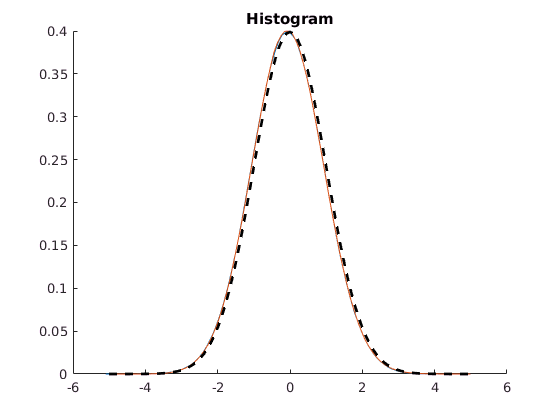


figure(6);clf; title('Histogram'); hold on;
ksdensity(Res1(:))
ksdensity(Res2(:))
plot(-5:.1:5,normpdf(-5:.1:5,0,1),'--k','linewidth',2)

%legend('Cstk', 'noCstk','Theorical')



## Very simple exemple: 3x3 grid.

clear all;clc;
% Create the 5x5 grid
grid_gen.sx = 2;
grid_gen.sy = 2;
grid_gen.x = 0:4;
grid_gen.y = 0:4;

% no hard data yet
sigma_true=[];
sigma.d=0;
sigma.x=0;
sigma.y=0;
sigma.n=1;

% Create the parm structure
parm.gen.covar.modele = [4 2 2 0];
parm.gen.covar.c = 1;
parm.k.wradius = Inf; % force to take all point
parm.k.nb_neigh = [0 0 0 0 0; Inf Inf Inf Inf Inf];
parm.saveit = false;
parm.neigh = 0;
parm.nscore = 0;
parm.par = 0;
parm.n_realisation  = 10000;
parm.cstk = true;
parm.seed = 1;

parm.path = 'distence_+';
[Res, ~, ~, parm, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);

Simulation 1/1 finished in : 21.9754


Res_1_t = reshape([Res{end}.m{:}],Res{end}.ny,Res{end}.nx,parm.n_realisation);

parm.path = 'distence_-';
[Res, ~, ~, parm, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);

Simulation 1/1 finished in : 21.0272


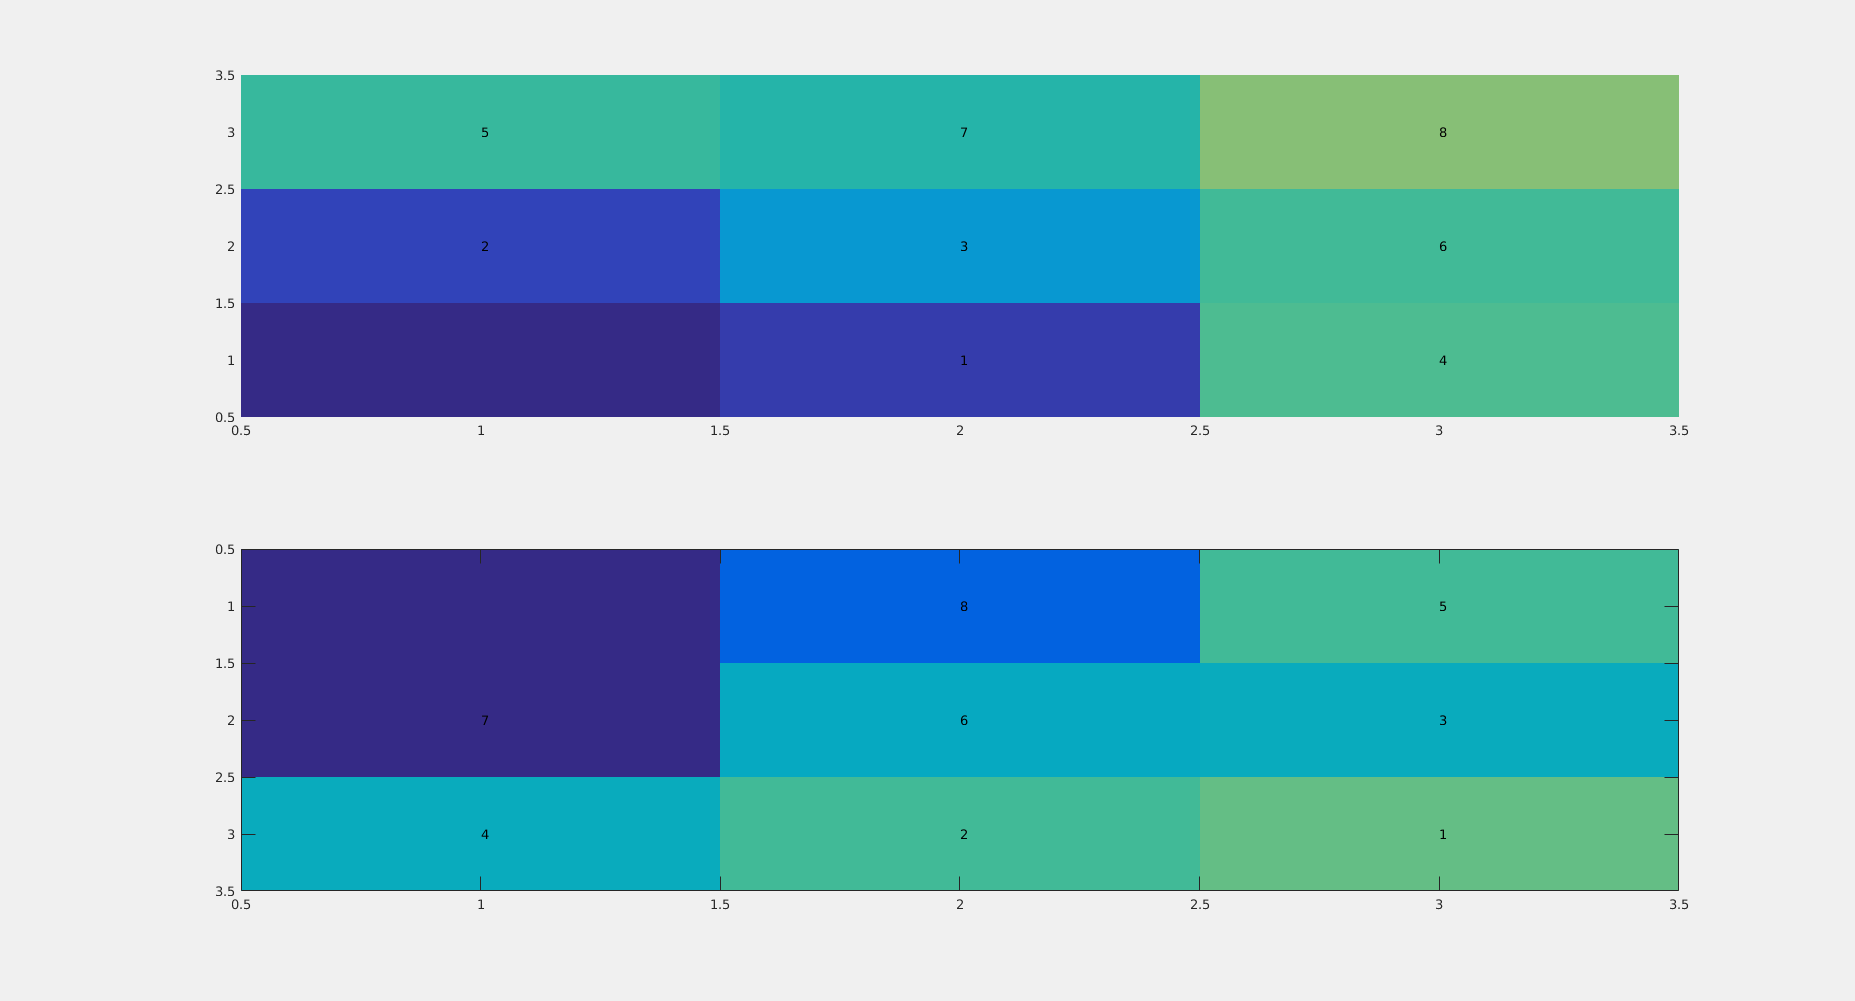

Res_2_t = reshape([Res{end}.m{:}],Res{end}.ny,Res{end}.nx,parm.n_realisation);

figure(2);clf
subplot(2,1,1); hold on;
imagesc(std(Res_1_t,[],3)); caxis([.95 1.05])
text(Res{end}.X(fliplr(Res{end}.sim.xy_r))'+1 , Res{end}.Y(fliplr(Res{end}.sim.xy_r))'+1,num2cell([1:8]))
subplot(2,1,2)
imagesc(std(Res_2_t,[],3)); caxis([.95 1.05])
text(Res{end}.X(Res{end}.sim.xy_r)'+1 , Res{end}.Y(Res{end}.sim.xy_r)'+1,num2cell([1:Res{end}.sim.n]))



figure(3);clf
subplot(1,2,1); hold on;
imagesc(max(abs(Res_1_t),[],3)); caxis([3 6])
text(Res{end}.X(fliplr(Res{end}.sim.xy_r))'+1 , Res{end}.Y(fliplr(Res{end}.sim.xy_r))'+1,num2cell([1:8]))
set(gca, 'Ydir', 'reverse')
subplot(1,2,2)
imagesc(max(abs(Res_2_t),[],3)); caxis([3 6])
text(Res{end}.X(Res{end}.sim.xy_r)'+1 , Res{end}.Y(Res{end}.sim.xy_r)'+1,num2cell([1:Res{end}.sim.n]))


parm.path = 'maximize';
[Res, ~, ~, parm, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);
Res_3_t = reshape([Res{end}.m{:}],Res{end}.ny,Res{end}.nx,parm.n_realisation);
imagesc(Res_3_t)
text(Res{end}.X(Res{end}.sim.xy_r)'+1 , Res{end}.Y(Res{end}.sim.xy_r)'+1,num2cell([1:Res{end}.sim.n]))
text(Res{1}.X(Res{1}.sim.xy_r)'+1 , Res{1}.Y(Res{1}.sim.xy_r)'+1,num2cell([1:Res{1}.sim.n]))

## Synthetique exemple

Test with 3 points A,B,C. where A is known. Try to find the pdf of B and C depending on the path, variogram and distence AB BC

We get very similar pdf.

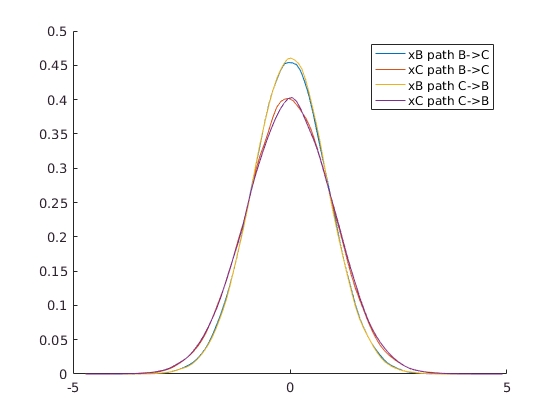

AB=1;
BC=.5;
c0=0;
c=1;
r=1;
g = @(h) c*exp(-h/r);
xA = 0;

gAB = g(AB);
gAC = g(AB+BC);
gBC = g(BC);

n=100000;
xB1=nan(1,n);
xC1=nan(1,n);
xB2=nan(1,n);
xC2=nan(1,n);

% Path B->C
xB1_std = c - gAB^2;
l = [c gAB;gAB c]\[gAC; gBC];
xC1_std = c - [gAC gBC]*l;

for i=1:n
    % xA = 1;%normrnd(0,1);
    xB1_m = gAB*xA;
    xB1(i) = normrnd(xB1_m,xB1_std);
    xC1_m = [xA xB1(i)]*l;
    xC1(i) = normrnd(xC1_m,xC1_std);
end

% Path C->B

xC2_std = c - gAC^2;
l = [c gAC;gAC c]\[gAB; gBC];
xB2_std = c - [gAB gBC]*l;

for i=1:n
    % xA = 1;%normrnd(0,1);
    xC2_m = gAC*xA;
    xC2(i) = normrnd(xC2_m,xC2_std);
    xB2_m = [xA xC2(i)]*l;
    xB2(i) = normrnd(xB2_m,xB2_std);
end

% std(abs(xA-xC))-(1-gAC);
% std(abs(xA-xB))-(1-gAB);
% std(abs(xB-xC))-(1-gBC);

figure(5); clf; hold on;
ksdensity(xB1);ksdensity(xC1);
ksdensity(xB2);ksdensity(xC2);
legend('xB path B->C', 'xC path B->C', 'xB path C->B', 'xC path C->B')

Var cova

clear all;clc;
% Create the 5x5 grid
grid_gen.sx = 4;
grid_gen.sy = 4;
grid_gen.x = 0:2^grid_gen.sx;
grid_gen.y = 0:2^grid_gen.sy;

% no hard data yet
sigma_true=[];
sigma.d=[];
sigma.x=[];
sigma.y=[];
sigma.n=0;

% Create the parm structure
parm.gen.covar.modele = [4 10 10 0];
parm.gen.covar.c = 1;
parm.k.wradius = 1.3; % force to take all point
parm.k.nb_neigh = [0 0 0 0 0; Inf Inf Inf Inf Inf];
parm.saveit = false;
parm.neigh = 0;
parm.nscore = 0;
parm.par = 0;
parm.n_realisation  = 1;
parm.cstk = true;
parm.seed = 1;
parm.varcovar=1;

% k=grid_gen.nxy*.05;
% sigma = sampling_pt(grid_gen,sigma_true,2,k);

parm.scale=[4;4];
parm.neigh = 0;
parm.k.nb_neigh = [0 0 0 0 0; 280 280 280 280 280]; parm.k.wradius = 280; 
[Res_ref, ~, ~, parm, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);

Simulation 1/1 finished in : 1.9947



parm.k.nb_neigh = [0 0 0 0 0; 5 5 5 5 0];
[Res_5, ~, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);

Simulation 1/1 finished in : 0.47018



parm.k.nb_neigh = [0 0 0 0 0; 2 2 2 2 2];
[Res_2, ~, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);

Simulation 1/1 finished in : 0.37725



parm.k.nb_neigh = [0 0 0 0 0; 30 30 30 30 0];
[Res_30, ~, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);

Simulation 1/1 finished in : 0.98526



parm.neigh = 1;parm.k.wradius = 1.3; 
parm.k.nb_neigh = [0 0 0 0 0; 30 30 30 30 0];
[Res_30_neigh, ~, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);

Simulation 1/1 finished in : 1.5342


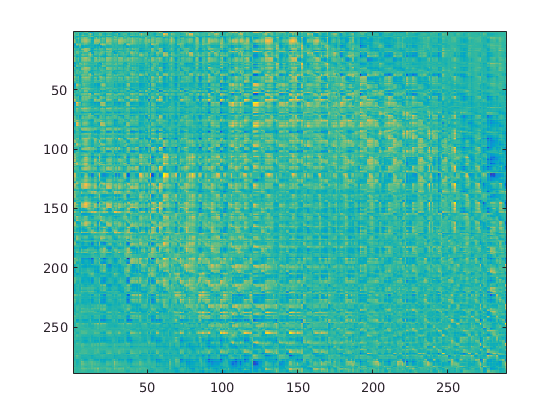


nu = @(res,res_ref) full( sqrt(sum((res-res_ref).^2)) / sqrt( sum(res_ref.^2)));
figure; imagesc(full(Res_5{end}.varcovar.CY)- full(Res_ref{end}.varcovar.CY))

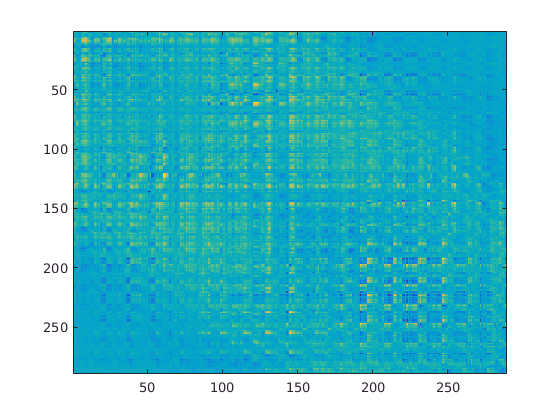

figure; imagesc(full(Res_2{end}.varcovar.CY)- full(Res_ref{end}.varcovar.CY))

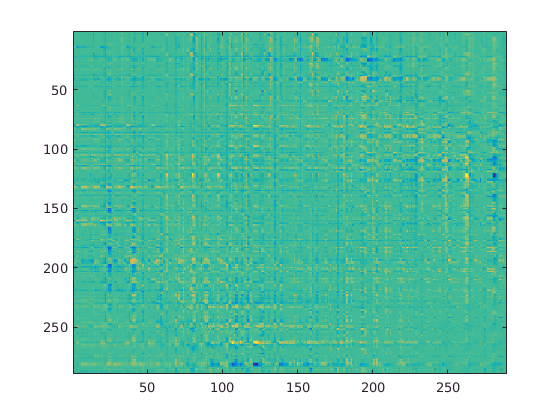

figure; imagesc(full(Res_30{end}.varcovar.CY)- full(Res_ref{end}.varcovar.CY))


nu(Res_2{end}.varcovar.CY,Res_ref{end}.varcovar.CY)

ans = 0.1967

nu(Res_5{end}.varcovar.CY,Res_ref{end}.varcovar.CY)

ans = 0.1056

nu(Res_30{end}.varcovar.CY,Res_ref{end}.varcovar.CY)

ans = 0.0277

nu(Res_30_neigh{end}.varcovar.CY,Res_ref{end}.varcovar.CY)

ans = 2.0910












parm.k.nb_neigh = [0 0 0 0 0; Inf Inf Inf Inf Inf];
parm.scale=[4;4];
parm.seed = 2;

parm.path = 'row-by-row';
[Res, ~, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);

Error using nan
NaN and Inf not allowed.

Error in kriging (line 41)
        sel_ss_idx{q}=nan(krig.nb_neigh(2,q),2);

Error in SGSIM>SGSIM_in (line 475)
            pt.krig = kriging(pt,Res{i_scale},Prim,krig,parm,1);

Error in 

a(1)=full(sqrt( sum(sum(Res{end}.varcovar.CY.^2))));

parm.path = 'spiralout';
[Res, ~, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);
a(2)=full(sqrt( sum(sum(Res{end}.varcovar.CY.^2))))

parm.path = 'spiralin';
[Res, ~, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);
a(3)=full(sqrt( sum(sum(Res{end}.varcovar.CY.^2))))

parm.path = 'maximize';
[Res, ~, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);
a(4)=full(sqrt( sum(sum(Res{end}.varcovar.CY.^2))))

parm.path = 'random';
[Res, ~, ~, ~, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);
a(5)=full(sqrt( sum(sum(Res{end}.varcovar.CY.^2))))


clear all;clc;
% Create the 5x5 grid
grid_gen.sx = 6;
grid_gen.sy = 6;
grid_gen.x = 0:2^grid_gen.sx;
grid_gen.y = 0:2^grid_gen.sy;

% no hard data yet
sigma_true=[];
sigma.d=[];
sigma.x=[];
sigma.y=[];
sigma.n=0;

% Create the parm structure
parm.gen.covar.modele = [4 10 10 0];
parm.gen.covar.c = 1;
% parm.k.wradius = 1.3; % force to take all point
% parm.k.nb_neigh = [0 0 0 0 0; Inf Inf Inf Inf Inf];
parm.saveit = false;
parm.neigh = 0;
parm.nscore = 0;
parm.par = 0;
% parm.n_realisation  = 1;
% parm.cstk = true;
parm.seed = 1;
parm.varcovar=true;
parm.scale=[6;6];

% the true covariance matrix for unconditional model
X = repmat(grid_gen.x,numel(grid_gen.y),1);
Y = repmat(grid_gen.y',1,numel(grid_gen.x));
CY=covardm_perso([X(:) Y(:)],[X(:) Y(:)],parm.gen.covar.modele,parm.gen.covar.c,parm.k.cx);
nu = @(res,res_ref) full( sqrt(sum((res(:)-res_ref(:)).^2)) / sqrt( sum(res_ref(:).^2)));

% the true true covariance matrix
lam = kriging_all_varcovar(Res{end},parm);


%% Test 1 : changing the number of neighboor
nb_neigh=[3 5 10 30 100];
t_nb_neigh =[4.7202,5.8498, 7.0764, 10.7834, 15.528, 24.9882]
for i_nb_neigh=1:numel(nb_neigh)
    parm.k.nb_neigh = [0 0 0 0 0; repmat(nb_neigh(i_nb_neigh),1,5)];
    [Res{i_nb_neigh}, ~, ~, parm, ~] = SGSIM(sigma,sigma_true,grid_gen,parm);
    nu_nb_neigh(i_nb_neigh) = nu(Res{i_nb_neigh}{end}.varcovar.CY,CY)
end
figure; hold on;
plot(nb_neigh,nu_nb_neigh,'-x')
plot(nb_neigh,t_nb_neigh,'-x')

figure;
for i_nb_neigh=1:numel(nb_neigh)
    subplot(numel(nb_neigh),1,i_nb_neigh);
    imagesc(full(Res{i_nb_neigh}{end}.varcovar.CY)-CY)
end

